resolution = 1200;

## 2G

a11=-0.5606; b11=+1.0000; b10=1 / ((1+1)/(1-0.5606)); % not correct scale factor
a21=-1.1587; a22=+0.6184;
b21=+1.4920; b22=+1.0000; b20=1 / ((1+1.4920+1)/(1-1.1587+0.6184)); % not correct scale factor

w1=0; % registers for filter 1
w2=[0 0]; % registers for filter 2

x=[1 zeros(1,100)]; % Input time Series

y_1=zeros(1,101); % output time Series, Filter 1
y_2=zeros(1,101); % output time Series, Filter 2

for n=1:100 % for loop
    sm1=x(n)-a11*w1; % input sum, filter 1
    s1 =sm1+b11*w1; % output sum, filter 1
    y_1(n)=b10*s1; % scale filter output, filter 1
    w1=sm1; % update register, filter 1

    sm2=y_1(n)-a21*w2(1)-a22*w2(2); % input sum, filter 2
    s2 =sm2+b21*w2(1)+b22*w2(2); % output sum, filter 2
    y_2(n)=b20*s2; % scale filter output, filter 2
    w2=[sm2 w2(1)]; % update registers, filter 2
end

## Plots for $h_1[n]$

figure()
subplot(2,1,1)
hold on
stem(0:1:100,y_1,'b')
title('Impulse Response, $h_1[n]$')
ylabel('Response')
xlabel('Time, $n$')
axis([0 100 -0.1 0.4])
hold off

b = [b10 b10]

b =     0.2197    0.2197


a = [1 -0.5606]

a =     1.0000   -0.5606


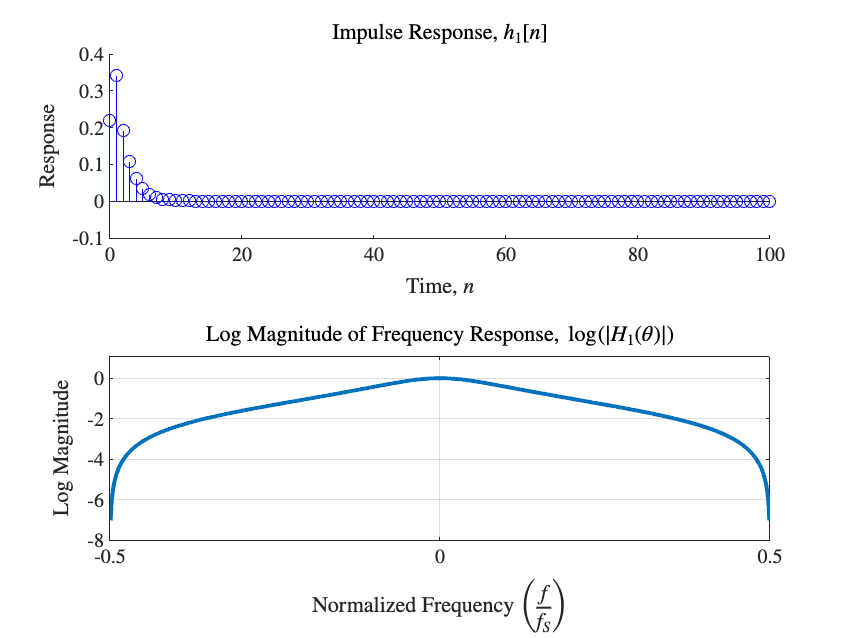

hold on
[H,~]=freqz(b,a,1000,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/1000:0.5-1/1000);
subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_1(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/2G_H1.png', 'Resolution',resolution);

## Plots for $h_2[n]$


figure()
subplot(2,1,1)
hold on
stem(0:1:100,y_2,'b')
title('Impulse Response, $h_2[n]$')
ylabel('Response')
xlabel('Time, $n$')
axis([0 100 -0.1 0.4])
hold off

b = [b20 b20*1.4920 b20]

b =     0.1316    0.1964    0.1316


a = [1 -1.1587 0.6184]

a =     1.0000   -1.1587    0.6184


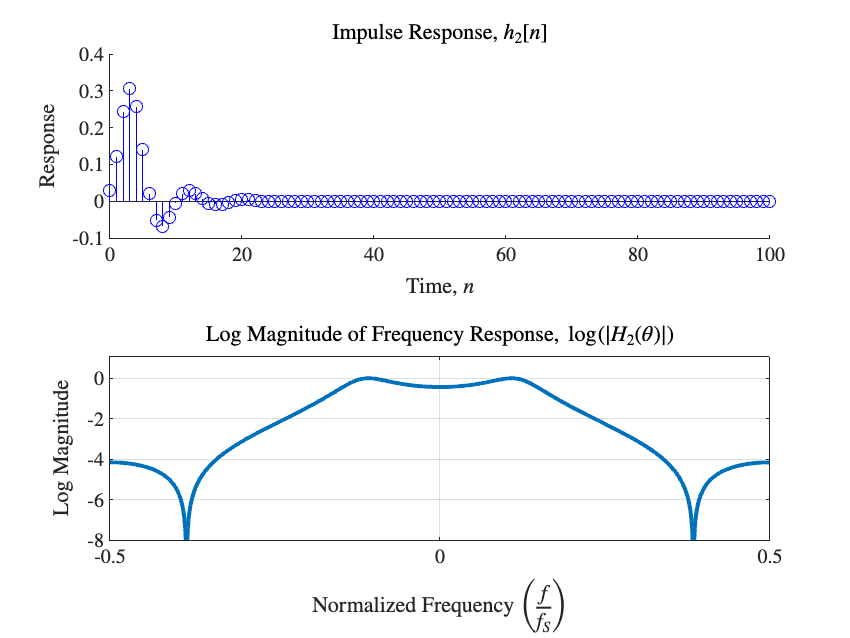

hold on
[H,~]=freqz(b,a,1000,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/1000:0.5-1/1000);
subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_2(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')
% exportgraphics(gcf, 'TeX/images/2G_H2.png', 'Resolution',resolution);